% impulse response LHP Poles

%setup time range
t = 0:0.02:10

t =          0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800


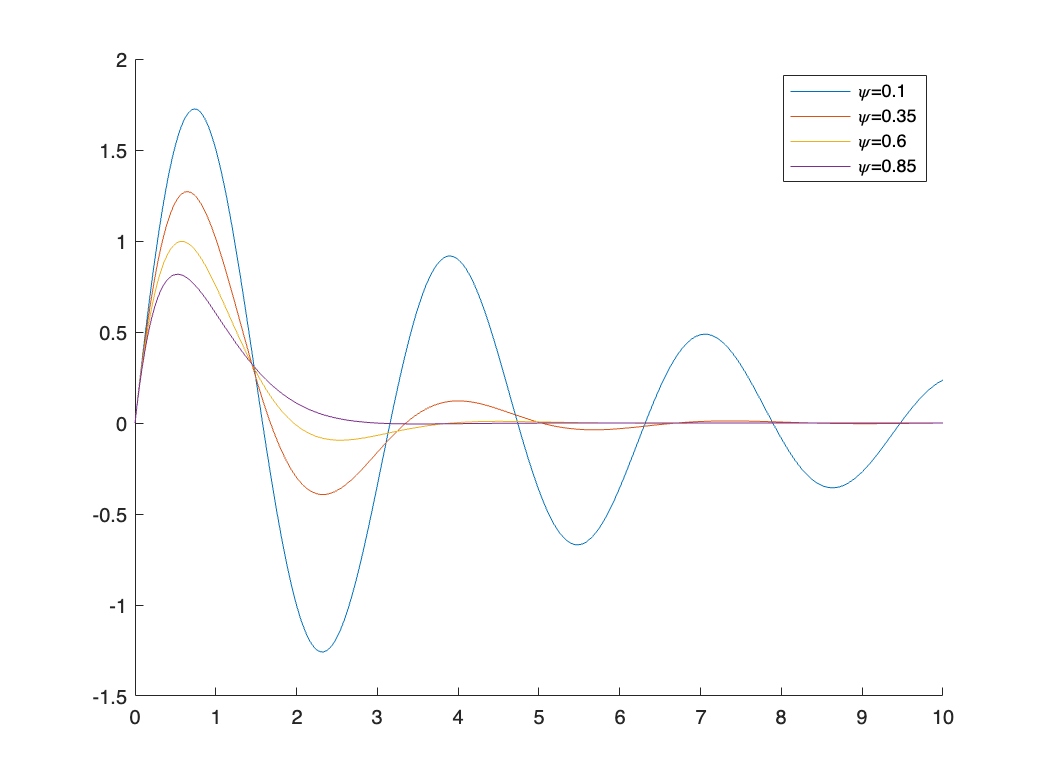


%set natural frequency of the system
wn = 2;

%go into s-plane alphanumberics
s = tf('s');

%initiate Latex extension
set(0,'defaulttextinterpreter','latex')

%plot all figures on the same graph
figure; hold on
plotLegend = legend('Location','northeast');

% ******* Plot the time domain function from the Inverse Laplace transform
%loop the damping coefficient psi
for psi = 0.1:0.25:1
    H = (wn^2)/((s + psi*wn)^2 + ((wn^2*(1 - psi^2))));
    y = impulse (H,t);
    plot (t,y)
    plotLegend.String{end} = '\psi=' + string(psi);
end;

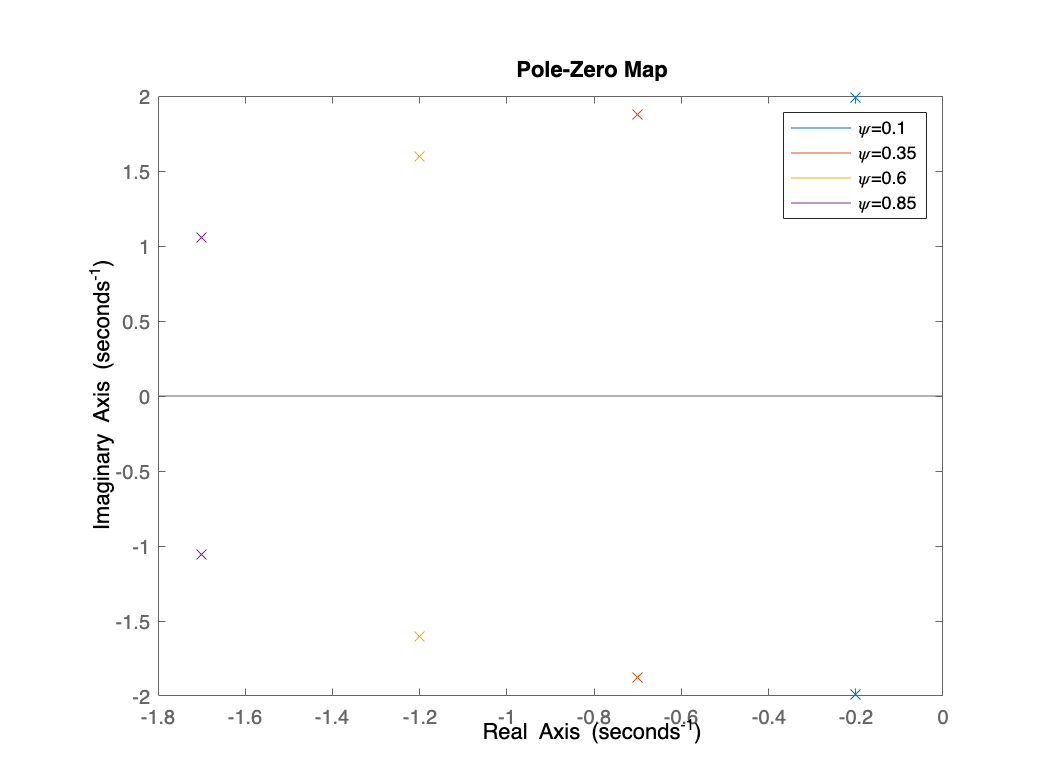


%******* Plot the pole locations
figure; hold on
plotLegend = legend('Location','northeast');
for psi = 0.1:0.25:1
    H = (wn^2)/((s + psi*wn)^2 + ((wn^2*(1 - psi^2))));
    y = impulse (H,t);
    pzplot(H)
    plotLegend.String{end} = '\psi=' + string(psi);
end;

% impulse response RHP Poles

t = 0:0.02:10

wn = 2;

t =          0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800


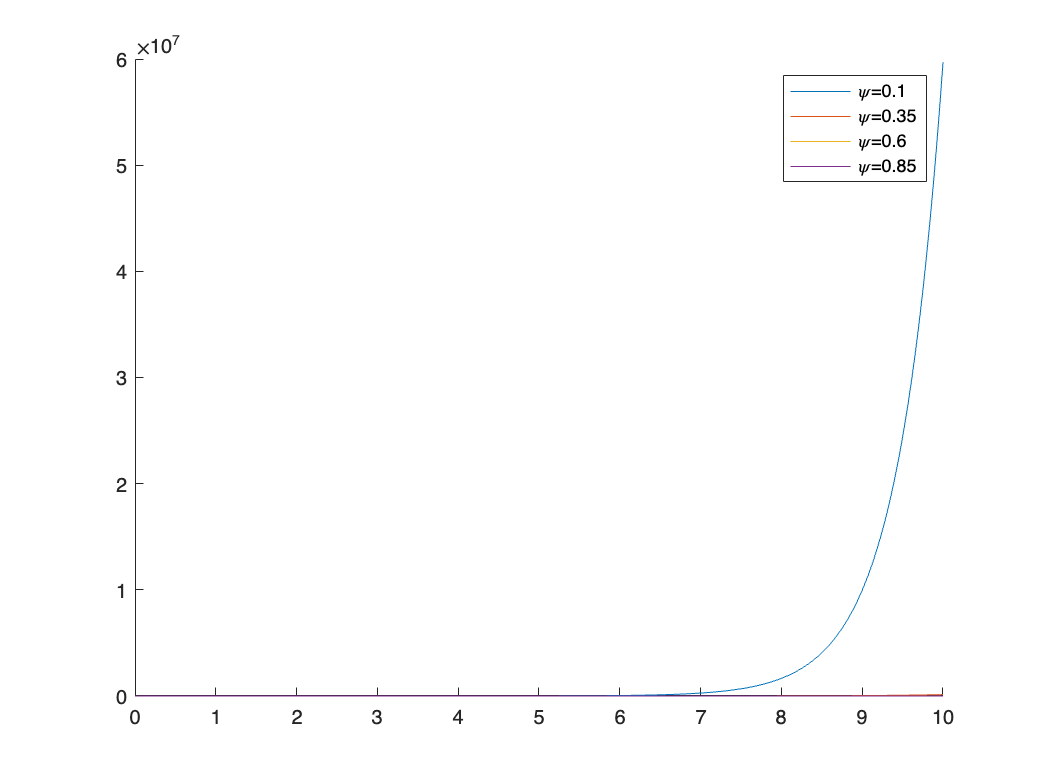


s = tf('s');
set(0,'defaulttextinterpreter','latex')
figure; hold on
plotLegend = legend('Location','northeast');
for psi = 0.1:0.25:1
    H = (wn^2)/((s + psi*wn)^2 - ((wn^2*(1 - psi^2))));
    y = impulse (H,t);
    plot (t,y)
    plotLegend.String{end} = '\psi=' + string(psi);
end;

figure; hold on

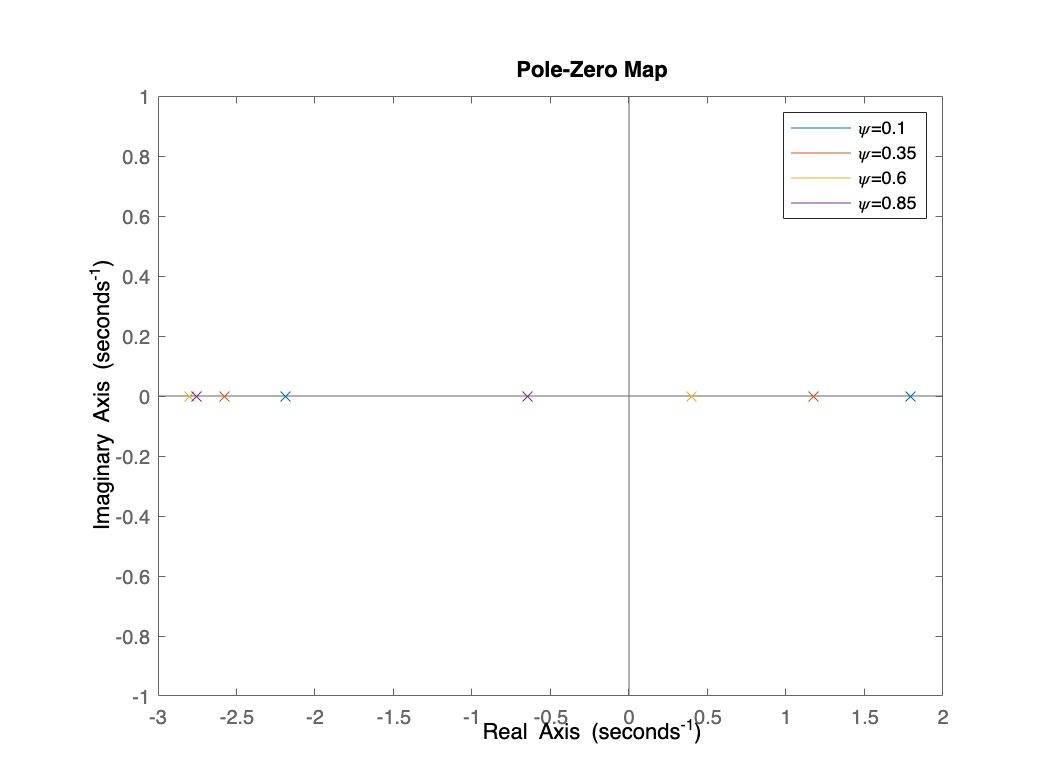

plotLegend = legend('Location','northeast');
for psi = 0.1:0.25:1
    H = (wn^2)/((s + psi*wn)^2 - ((wn^2*(1 - psi^2))));
    y = impulse (H,t);
    pzplot(H)
    plotLegend.String{end} = '\psi=' + string(psi);
end;
 